# Medical Image Processing - Worksheet 3

**Authors: Cristina Salinas, Irene Amengual and Tobias Haider**

## Preparation

### Set up the initial image

image_file = fopen("data/ThoraxXray_500x420_noise");
xray_image = fread(image_file, [500, 420], "float32", "ieee-be");

### Display the image

The original contains very visible noise.

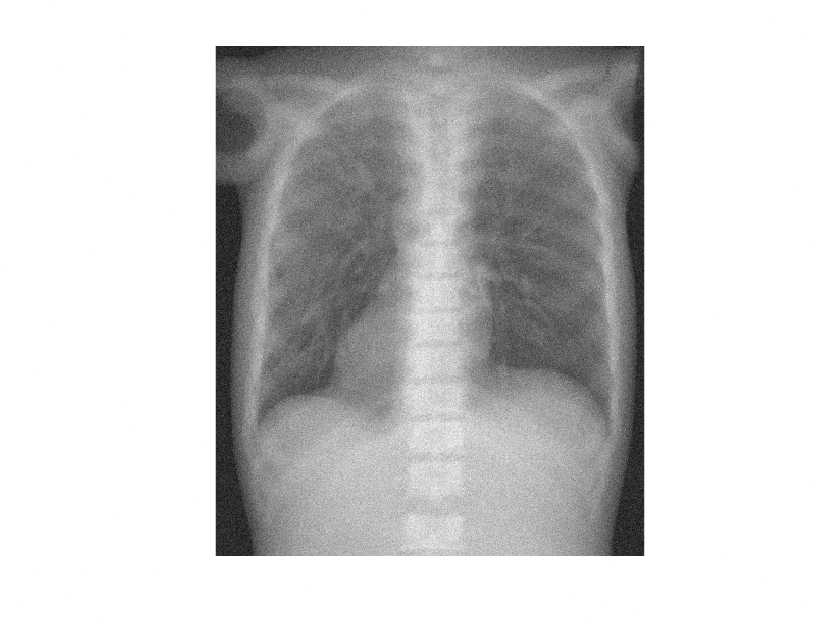

imshow(xray_image, [])

### Define global parameters

pixel_size = 0.8 % mm

pixel_size = 0.8000

## Task 1: Filtering in spatial domain

Build your own function called SpatialFilt that filters an image with a Gaussian filter. 

### SpacialFilt function

function filt_image = SpatialFilt(myimage, im_pixel_size, k_size, k_sigma, edge_fill)
    if mod(k_size, 2) == 0
        error("k_size must be an odd integer.");
    end
    padding_size = floor(k_size / 2);
    [size_x, size_y] = size(myimage);

    if edge_fill == 0
            padded_image = zeros(size_x + 2 * padding_size, size_y + 2 * padding_size);
            padded_image(padding_size + 1:end - padding_size, padding_size + 1:end - padding_size) = myimage;
    elseif edge_fill == 1
        padded_image = [repmat(myimage(1, :), padding_size, 1); myimage; repmat(myimage(end, :), padding_size, 1)];
        padded_image = [repmat(padded_image(:, 1), 1, padding_size), padded_image, repmat(padded_image(:, end), 1, padding_size)];
    else
        error("edge_fill must be 0 or 1.")
    end

    % Build the filter
    filter_center = (k_size + 1) / 2;
    [filter_pos_X, filter_pos_Y] = meshgrid(1:k_size, 1:k_size);
    filter_distances = sqrt((filter_pos_X - filter_center).^2 + (filter_pos_Y - filter_center).^2); % Task desciption does not specify the norm, so Euclidean is chosen
    gaussian_filter = exp(-(filter_distances.^2)/(2 * k_sigma / im_pixel_size));
    gaussian_filter = gaussian_filter / sum(gaussian_filter(:));

    % Create the filtered image
    filt_image = zeros(size(myimage));
    
    for i = 1:size_x
        for j = 1:size_y
            % Extract local region from padded image
            % Note that an offset (padding_size) must be added when indexing the padded image
            image_region = padded_image(i:i + 2 * padding_size, j:j + 2 * padding_size);
            % Multiply region pixels with normalized kernel
            filt_image(i, j) = sum(image_region(:) .* gaussian_filter(:));
        end
    end
end

### Testing SpatialFilt function

k_size = 21;
k_sigma = 1.5;
image_filtered_spatial = SpatialFilt(xray_image, pixel_size, k_size, k_sigma, 0);

## Task 2: Filtering in Fourier domain

Build your own function called FourierFilt that filters an image in the Fourier domain with a Gaussian low pass filter.

function filt_image = FourierFilt(myimage, im_pixel_size, k_sigma_spat, zero_pad)
    [size_x, size_y] = size(myimage);
    % Apply zero padding
    if size_x <= size_y
        padding_x = zero_pad / 2;
        padding_y = max(0, size_x + zero_pad - size_y) / 2; % Try to make the padded image square
    else
        padding_y = zero_pad / 2;
        padding_x = max(0, size_y + zero_pad - size_x) / 2; % Try to make the padded image square
    end
    padded_image = zeros(size_x + 2 * padding_x, size_y + 2 * padding_y);
    padded_image(padding_x + 1:end - padding_x, padding_y + 1:end - padding_y) = myimage;

    [size_padded_x, size_padded_y] = size(padded_image);
    fov_x = size_padded_x * im_pixel_size;
    fov_y = size_padded_y * im_pixel_size;
    
    % Compute the Fourier Transform of the padded image
    F_image = fftshift(fft2(padded_image));

    % Build the filter for the Fourier domain
    [horizontal_freq, vertical_freq] = meshgrid((-size_padded_y / 2:size_padded_y / 2 - 1) / fov_y, (-size_padded_x / 2:size_padded_x / 2 - 1) / fov_x);
    freq_radius = sqrt(horizontal_freq.^2 + vertical_freq.^2);
    k_sigma_freq = 1 / (2 * pi * k_sigma_spat);
    F_gaussian = exp(-(freq_radius.^2) / (2 * k_sigma_freq^2));
    F_gaussian = F_gaussian / max(F_gaussian(:)); % Normalize the filter

    % Apply the filter to the image
    F_filtered = F_image .* F_gaussian;

    % Compute inverse Fourier transform and construct the output
    filtered_padded_image = real(ifft2(ifftshift(F_filtered)));
    filt_image = filtered_padded_image(padding_x + 1:padding_x + size_x, padding_y + 1:padding_y + size_y);
end

### Testing FourierFilt

k_sigma_spat = 1.5;
zero_pad = 420;
image_filtered_frequency = FourierFilt(xray_image, pixel_size, k_sigma_spat, zero_pad);

## Results

### Plot of processed images

This summary shows the results of filtering side by side.

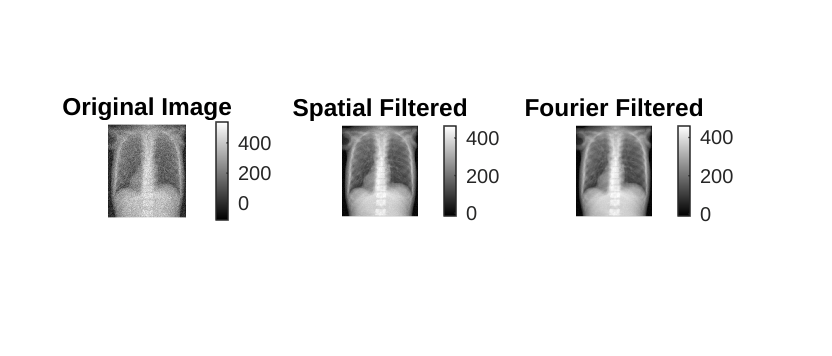

figure(1); 
clf;
set(gcf,'Position', [100, 100, 1400, 600]);
subplot(1,3,1);
imshow(xray_image, []);
title('Original Image');
colorbar;

subplot(1,3,2);
imshow(image_filtered_spatial, []);
title('Spatial Filtered');
colorbar;

subplot(1,3,3);
imshow(image_filtered_frequency, []);
title('Fourier Filtered');
colorbar;

### Plot of image differences

The following plot shows the differences of the filtered images to the original image.

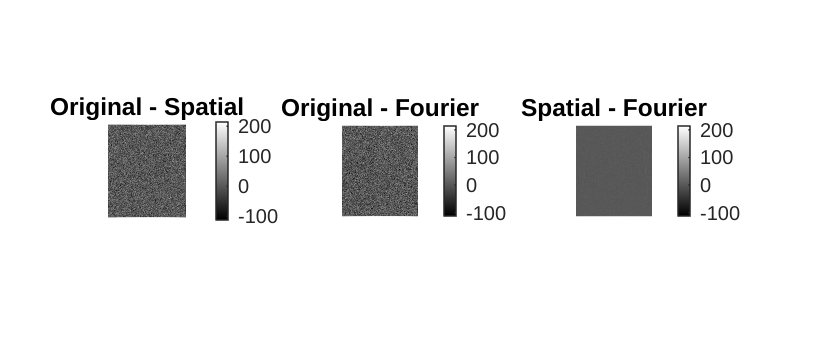

% Compute difference images
diff_a = xray_image - image_filtered_spatial;
diff_b = xray_image - image_filtered_frequency;
diff_c = image_filtered_spatial - image_filtered_frequency;

% Combine all to get a common value range
all_diff = [diff_a(:); diff_b(:); diff_c(:)];
diff_range = [min(all_diff), max(all_diff)];

figure(2);
clf;
set(gcf, 'Position', [100, 100, 1400, 600]);
subplot(1,3,1);
imshow(diff_a, diff_range);
title('Original - Spatial');
colorbar;

subplot(1,3,2);
imshow(diff_b, diff_range);
title('Original - Fourier');
colorbar;

subplot(1,3,3);
imshow(diff_c, diff_range);
title('Spatial - Fourier');
colorbar;
hold off;